# QUESTION - 2

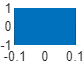

clear;
close all;
clc;

fc = 10000;
fm = 100;
A = 1;
t = (-0.01:0.000001:+0.01); 
a1 = cos(2*pi*fm*t).*cos(2*pi*fc*t);
a2 = sin(2*pi*fm*t).*sin(2*pi*fc*t);
Vlsb = a1+a2;

figure(1);
plot(t,Vlsb);

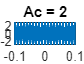



%part B
 % case_1
Ac = 2;  %amplitude of the carrier signal

a3 = cos(2*pi*fc*t);
VlsbAm  = Ac*a3 + A*Vlsb;
figure(2);
plot(t,VlsbAm);
title("Ac = 2");

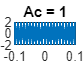


% case_2
Ac = 1;
VlsbAm  = Ac*a3 + A*Vlsb;
figure(3);
plot(t,VlsbAm);
title("Ac = 1");

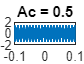


% case_3
Ac = 0.5;
VlsbAm  = Ac*a3 + A*Vlsb;
figure(4);
plot(t,VlsbAm);
title("Ac = 0.5");

## part c

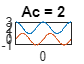

% Here mt= cos(2*pi*fm*t) so the hilbert transform of it will vary
%by 90 degree  and m^t= sin(2*pi*fm*t)

%provethe given equation, we can plot the graphs of RHS and LHS on
% same

t = (-0.01:0.000001:+0.01);       % time period
fm = 100;                          % message frequency
fc = 10000;                        % carrier frequency
Vlsb = cos(2*pi*(fc-fm)*t);        % single-sideband modulation wave
% here 
% for Ac = 2
Ac=2;
figure(5);
plot(t,abs(Ac+cos(2*pi*fm*t)) , t,sin(2*pi*fm*t));
title("Ac = 2");

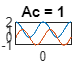


%for ac = 1
Ac=1;
figure(5);
plot(t,abs(Ac+cos(2*pi*fm*t)) , t,sin(2*pi*fm*t));
title("Ac = 1");


%{ from above plots for diffent value of ac follwing equation is verified
 
% |Ac + m(t)| > |m_hat(t)| is verified as we increase the value of ac

% as we can see at ac = 2 its not intersecting and will intersect at all
% othe value se it is verified at ac = 2 












